# Global path planning

## Scenario 1

### Map only

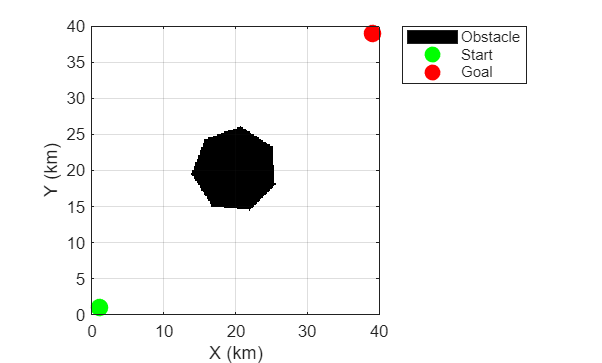

clear; 
clc; 
close all;

%% World & grid
res = 5;    % cells per meter
Wm  = 40; 
Hm = 40;    % world size in meters
W   = Wm*res; 
H  = Hm*res;    % grid size in cells
occ = zeros(H, W);  % 0 free, 1 occupied
[xg, yg] = meshgrid(1:W, 1:H);

%% Polygon island parameters
cx = Wm/2;                 % island center x (m)
cy = Hm/2;                 % island center y (m)
nSides   = 7;              % number of vertices
radius_m = 6;              % approximate "radius" (m)
rot_deg  = 20;             % rotation of polygon (deg)

% Regular polygon vertices (m)
theta = linspace(0, 2*pi, nSides+1).';
theta(end) = [];                         % remove duplicate last = first
theta = theta + deg2rad(rot_deg);
vx_m = cx + radius_m*cos(theta);
vy_m = cy + radius_m*sin(theta);

% Convert vertices (m) -> grid cell indices
vx = round(vx_m * res);
vy = round(vy_m * res);

% Rasterize polygon to occupancy
islandMask = inpolygon(xg, yg, vx, vy);
occ(islandMask) = 1;

%% Build two maps: one for planning (inflated) and one for display (raw)
mapBase = binaryOccupancyMap(occ, res);    % NON-inflated, for visualisation

%% Start & goal (m)
startPose = [1, 1,  pi/4];
goalPose  = [39, 39, 0];

%% Show the NON-inflated map, then overlay the path
figure('Color','w'); 
show(mapBase); 
hold on;
title('');
xlabel('X (km)')
ylabel('Y (km)')

% Add dummy obstacle entry to legend (solid black square)
patch(NaN, NaN, 'k', 'DisplayName', 'Obstacle');

% Path & markers
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

legend('Location','northeastoutside');
axis equal; 
box on; 
grid on; 
xlim([0 40]);
ylim([0 40]);
hold off;

### Map with path

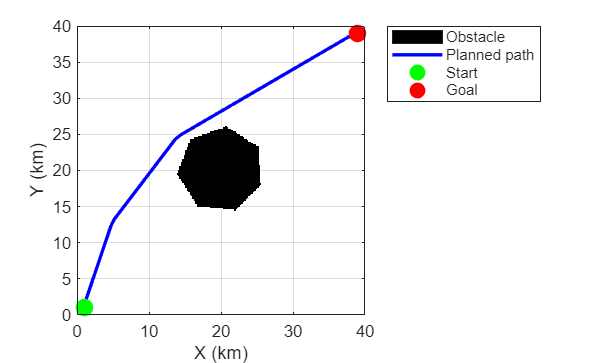

clear; 
clc; 
close all;

%% World & grid 
res = 5;                   % cells per meter
Wm  = 40; 
Hm = 40;         % world size in meters
W   = Wm*res; 
H  = Hm*res; % grid size in cells
occ = zeros(H, W);         % 0 free, 1 occupied
[xg, yg] = meshgrid(1:W, 1:H);

%% Polygon island parameters
cx = Wm/2;                 % island center x (m)
cy = Hm/2;                 % island center y (m)
nSides   = 7;              % number of vertices
radius_m = 6;              % approximate "radius" (m)
rot_deg  = 20;             % rotation of polygon (deg)

% Regular polygon vertices (m)
theta = linspace(0, 2*pi, nSides+1).';
theta(end) = [];                         % remove duplicate last = first
theta = theta + deg2rad(rot_deg);
vx_m = cx + radius_m*cos(theta);
vy_m = cy + radius_m*sin(theta);

% Convert vertices (m) -> grid cell indices
vx = round(vx_m * res);
vy = round(vy_m * res);

% Rasterize polygon to occupancy
islandMask = inpolygon(xg, yg, vx, vy);
occ(islandMask) = 1;

%% Build two maps: one for planning (inflated) and one for display (raw)
mapBase = binaryOccupancyMap(occ, res);    % NON-inflated, for visualisation
mapPlan = binaryOccupancyMap(occ, res);    % copy for planning
inflate(mapPlan, 0.5);                     % safety margin used by planner

%% Planner setup (use the inflated planning map)
ss = stateSpaceSE2;
ss.StateBounds = [mapBase.XWorldLimits; mapBase.YWorldLimits; [-pi pi]];

sv = validatorOccupancyMap(ss);
sv.Map = mapPlan;                          % collision checks use inflated map

planner = plannerHybridAStar(sv, MinTurningRadius=1.53);

%% Start & goal (m)
startPose = [1, 1,  pi/2];
goalPose  = [39, 39, 0];

%% Plan on the inflated map 
path = plan(planner, startPose, goalPose, SearchMode="exhaustive");

%% Show the NON-inflated map, then overlay the path
figure('Color','w'); 
show(mapBase); 
hold on;
title('');
xlabel('X (km)')
ylabel('Y (km)')

% Add dummy obstacle entry to legend (solid black square)
patch(NaN, NaN, 'k', 'DisplayName', 'Obstacle');

% Path & markers
plot(path.States(:,1), path.States(:,2), 'b-', 'LineWidth', 2, 'DisplayName','Planned path');
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

legend('Location','northeastoutside');
axis equal; 
box on; 
grid on; 
xlim([0 40]);
ylim([0 40]);
hold off;

## Scenario 2

### Map only

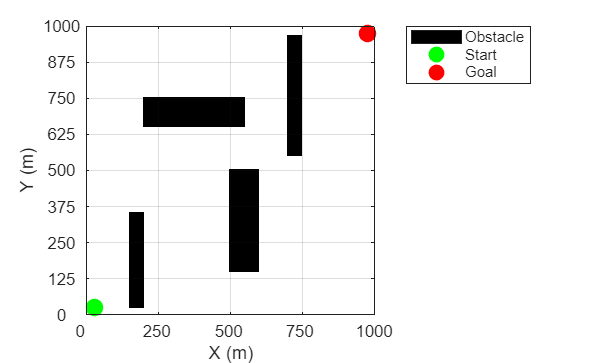

clear;
clc;
close all;

% Resolution & world
res = 5;              % cells per meter
Wm  = 40; 
Hm = 40;    % world size in meters
occ = zeros(200,200); % 200×200 grid (40×40 m at 5 cells/m)

% Rectangular obstacles (rows = y, cols = x) 
occ(130:195,  30:40)   = 1;  
occ(50:70,    40:110)  = 1;   
occ(100:170,  100:120) = 1;   
occ(7:90,     140:150) = 1;   

% Create occupancy map
map = binaryOccupancyMap(occ, res);

% Start & goal (m)
startPose = [1, 1];
goalPose  = [39, 39];

% Plot only obstacles, start, and goal
figure; 
hold on; 
box on;
axis equal;

show(map);  % plots the occupancy grid
ax = gca;
ax.Layer = 'top';

patch(NaN, NaN, 'k', 'DisplayName','Obstacle'); % dummy for legend

% Plot start/goal
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

% Scale axes from 40 m → 1000 m ---
scale = 1000/40;   % = 25
xt = get(gca,'XTick'); 
yt = get(gca,'YTick');
set(gca,'XTickLabel', xt * scale);
set(gca,'YTickLabel', yt * scale);

% Formatting
title('');
box on;
grid on;
xlabel('X (m)');
ylabel('Y (m)');
legend('Location','bestoutside'); 
hold off;

### Map with path

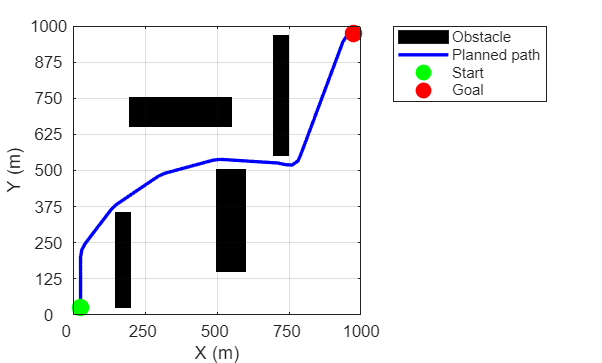

clear;
clc;
close all;

% Resolution & world 
res = 5;              % cells per meter
Wm  = 40; 
Hm = 40;    % world size in meters
occ = zeros(200,200); % 200×200 grid (40×40 m at 5 cells/m)

% Rectangular obstacles (rows = y, cols = x) 
occ(130:195,  30:40)   = 1;   
occ(50:70,    40:110)  = 1;   
occ(100:170,  100:120) = 1;   
occ(7:90,     140:150) = 1;   

%% Build two maps: one for planning (inflated) and one for display (raw)
mapBase = binaryOccupancyMap(occ, res);    % NON-inflated, for visualisation
mapPlan = binaryOccupancyMap(occ, res);    % copy for planning
inflate(mapPlan, 0.5);                     % safety margin used by planner

%% Planner setup (use the inflated planning map)
ss = stateSpaceSE2;
ss.StateBounds = [mapBase.XWorldLimits; mapBase.YWorldLimits; [-pi pi]];

sv = validatorOccupancyMap(ss);
sv.Map = mapPlan;                          % collision checks use inflated map

planner = plannerHybridAStar(sv, MinTurningRadius=1.53);

% Start & goal (m)
startPose = [1, 1, pi/2];
goalPose  = [39, 39, 0];

%% Plan on the inflated map 
path = plan(planner, startPose, goalPose, SearchMode="exhaustive");

% Plot only obstacles, start, and goal
figure; 
show(mapBase);
hold on; 
axis equal;
xlim([0 40]);
ylim([0 40]);

patch(NaN, NaN, 'k', 'DisplayName','Obstacle'); % dummy for legend

% Plot start/goal
plot(path.States(:,1), path.States(:,2), 'b-', 'LineWidth', 2, 'DisplayName','Planned path');
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

% Scale axes from 40 m → 1000 m 
scale = 1000/40;   % = 25
xt = get(gca,'XTick'); 
yt = get(gca,'YTick');
set(gca,'XTickLabel', xt * scale);
set(gca,'YTickLabel', yt * scale);

% Formatting
title('');
xlabel('X (m)');
ylabel('Y (m)');
legend('Location','bestoutside');
grid on; 
box on;
axis square
hold off;

## Scenario 3

### Map only

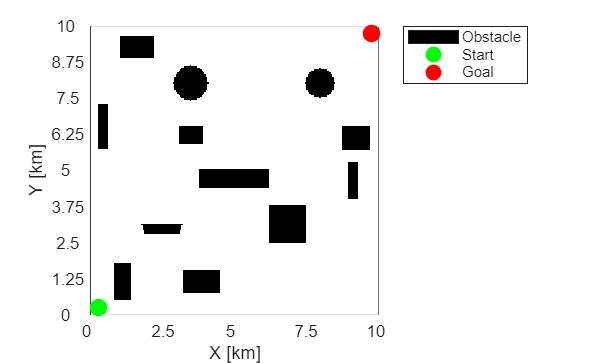

clear;
clc; 
close all;

res = 5;

% Build a 200×200 grid
occ = zeros(200,200);              
[xg, yg] = meshgrid(1:200, 1:200); 

% Rectangular obstacles
occ(125:150, 125:150)  = 1;     
occ(55:85,   6:12)     = 1;     
occ(170:185, 65:90)    = 1;     
occ(95:120,  180:186)  = 1;     
occ(70:82,   62:78)    = 1;     
occ(165:190, 17:28)    = 1;     
occ(100:112, 76:124)   = 1;     
occ(70:86,   176:194)  = 1;     
occ(8:22,    21:44)    = 1;     

% Circle 1
cx1 = 70; cy1 = 40; r1 = 12;   % radius = 12  
mask1 = (xg-cx1).^2 + (yg-cy1).^2 <= r1^2;
occ(mask1) = 1;

% Circle 2
cx2 = 160; cy2 = 40; r2 = 10;    % radius = 10
mask2 = (xg-cx2).^2 + (yg-cy2).^2 <= r2^2;
occ(mask2) = 1;

% Polygon barrier
px = [36 64 62 38];  
py = [138 138 144 144]; 
maskPoly = inpolygon(xg, yg, px, py);
occ(maskPoly) = 1;

% Create map
map = binaryOccupancyMap(occ, res);

% Start & Goal
startPose = [1, 1];
goalPose  = [39, 39];

% Plot
figure; 
hold on; 
axis equal;
show(map);
patch(NaN, NaN, 'k', 'DisplayName','Obstacle');  % dummy for legend

plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

% Force world bounds
xlim([0, 200/res]); 
ylim([0, 200/res]);

% Scale to 10 km world
scale = 10/40;  % 10 km / 40 m = 0.25 km per m
xt = get(gca,'XTick');
yt = get(gca,'YTick');
set(gca,'XTickLabel', xt * scale);  
set(gca,'YTickLabel', yt * scale);

xlabel('X [km]'); 
ylabel('Y [km]');
title('');
legend('Location','bestoutside');
grid on; 
box on; 
hold off;

### Map with path

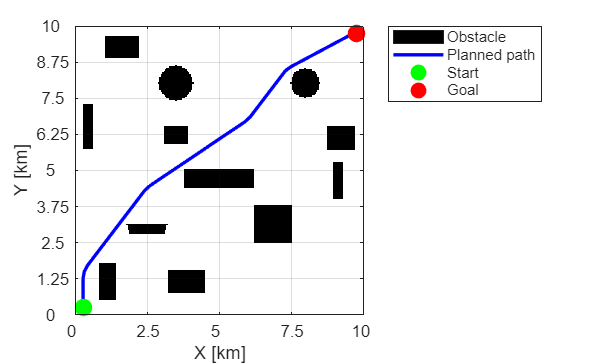

clear;
clc; 
close all;

res = 5;

% Build a 200×200 grid
occ = zeros(200,200);              
[xg, yg] = meshgrid(1:200, 1:200); 

% Rectangular obstacles 
occ(125:150, 125:150)  = 1;     
occ(55:85,   6:12)     = 1;     
occ(170:185, 65:90)    = 1;     
occ(95:120,  180:186)  = 1;     
occ(70:82,   62:78)    = 1;     
occ(165:190, 17:28)    = 1;     
occ(100:112, 76:124)   = 1;     
occ(70:86,   176:194)  = 1;     
occ(8:22,    21:44)    = 1;     

% Circle 1
cx1 = 70; cy1 = 40; r1 = 12;     % radius = 12
mask1 = (xg-cx1).^2 + (yg-cy1).^2 <= r1^2;
occ(mask1) = 1;

% Circle 2
cx2 = 160; cy2 = 40; r2 = 10;    % radius = 10
mask2 = (xg-cx2).^2 + (yg-cy2).^2 <= r2^2;
occ(mask2) = 1;

% Polygon barrier
px = [36 64 62 38];  
py = [138 138 144 144]; 
maskPoly = inpolygon(xg, yg, px, py);
occ(maskPoly) = 1;

%% Build two maps: one for planning (inflated) and one for display (raw)
mapBase = binaryOccupancyMap(occ, res);    % NON-inflated, for visualisation
mapPlan = binaryOccupancyMap(occ, res);    % copy for planning
inflate(mapPlan, 0.5);                     % safety margin used by planner

%% Planner setup (use the inflated planning map)
ss = stateSpaceSE2;
ss.StateBounds = [mapBase.XWorldLimits; mapBase.YWorldLimits; [-pi pi]];

sv = validatorOccupancyMap(ss);
sv.Map = mapPlan;                          % collision checks use inflated map

planner = plannerHybridAStar(sv, MinTurningRadius=1.53);

% Start & Goal
startPose = [1, 1, pi/2];
goalPose  = [39, 39, 0];

%% Plan on the inflated map
path = plan(planner, startPose, goalPose, SearchMode="exhaustive");

% Plot
figure(); 
show(mapBase);
hold on; 
axis equal;

patch(NaN, NaN, 'k', 'DisplayName','Obstacle');  % dummy for legend

plot(path.States(:,1), path.States(:,2), 'b-', 'LineWidth', 2, 'DisplayName','Planned path');
plot(startPose(1), startPose(2), 'go', 'MarkerFaceColor','g', 'MarkerSize', 10, 'DisplayName','Start');
plot(goalPose(1),  goalPose(2),  'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 10, 'DisplayName','Goal');

% Force world bounds
xlim([0, 200/res]); ylim([0, 200/res]);

% Scale to 10 km world
scale = 10/40;  % 10 km / 40 m = 0.25 km per m
xt = get(gca,'XTick');
yt = get(gca,'YTick');
set(gca,'XTickLabel', xt * scale);  
set(gca,'YTickLabel', yt * scale);

xlabel('X [km]'); 
ylabel('Y [km]');
title('');
legend('Location','bestoutside');
grid on; 
box on; 
hold off;